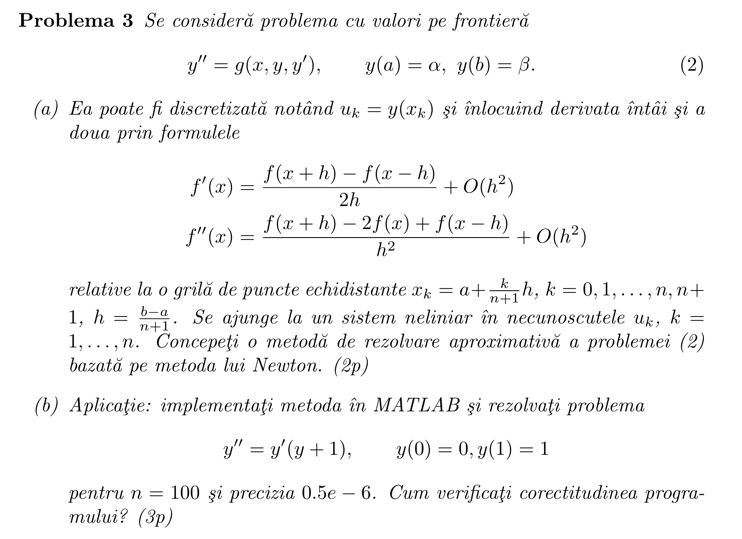

(*corectie*: $x_k =a+k\cdot h$)

## Solutie

### Primul subpunct

$\begin{array}{l}
y^{\prime } \left(x\right)=\frac{u_{k+1} -u_{k-1} }{2h}\\
{y^{\prime } }^{\prime } \left(x\right)=\frac{u_{k+1} -2u_k +u_{k-1} }{h^2 }\\
\mathrm{Deci}:\\
\frac{u_{k+1} -2u_k +u_{k-1} }{h^2 }=g\left(a+k\cdot h,u_k ,\frac{u_{k+1} -u_{k-1} }{2h}\right),k=1\ldotsn\Rightarrow \\
\Rightarrow q\left(u_{k+1} ,u_k ,u_{k-1} \right)=\;u_{k+1} -2u_k +u_{k-1} -h^2 \cdot g\left(a+k\cdot h,u_k ,\frac{u_{k+1} -u_{k-1} }{2h}\right)=0
\end{array}$.

Conditiile in capete:


$$u_0 =\alpha ,u_{n+1} =\beta$$


Avem n ecuatii si n necunoscute. Deoarece sistemul  este neliniar, este necesar sa rezolvam cu metoda lui Newton. Pentru asta, avem nevoie de derivatele partiale. In fiecare punct exista 3 necunoscute: $u_{k+1} ,u_k ,u_{k-1}$. Deci vom avea un sistem tridiagonal. Calculam derivatele partiale in fiecare punct:


$$\begin{array}{l}
\frac{\partial q}{\partial u_{k-1} }=1-h^2 \cdot \frac{-1}{2h}\cdot \frac{\partial g}{\partial u_{k-1} }\left(a+k\cdot h,u_k ,\frac{u_{k+1} -u_{k-1} }{2h}\right)=1+\frac{h}{2}\cdot \frac{\partial g}{\partial u_{k-1} }\left(a+k\cdot h,u_k ,\frac{u_{k+1} -u_{k-1} }{2h}\right)\\
\frac{\partial q}{\partial u_k }=-2-h^2 \frac{\partial g}{\partial u_{k-1} }\left(a+k\cdot h,u_k ,\frac{u_{k+1} -u_{k-1} }{2h}\right)\\
\frac{\partial q}{\partial u_{k+1} }=1-h^2 \cdot \frac{1}{2h}\cdot \frac{\partial g}{\partial u_{k+1} }\left(a+k\cdot h,u_k ,\frac{u_{k+1} -u_{k-1} }{2h}\right)=\frac{\partial q}{\partial u_{k+1} }=1-\frac{h}{2h}\cdot \frac{\partial g}{\partial u_{k+1} }\left(a+k\cdot h,u_k ,\frac{u_{k+1} -u_{k-1} }{2h}\right)
\end{array}$$


### Al doilea subpunct

function [u,val_f,nr_it]=SolveNewtonDiffEquationOrd2(g, a, b, alfa, beta, n, prec)
    h=(b-a)/(n+1);
    u0=init_newton_elem(n,a,b,alfa,beta);
    q=@(u1, u2, u3, k) (u1 - 2*u2 + u3 - h^2*g(a+k*h, u2, (u3-u1)/(2*h)));
    
    syms u [1 n];
    F=[q(alfa, u(1), u(2), 1)];
    for k=2:n-1
        F=[F; q(u(k-1), u(k), u(k+1), k)];
    end
    F=[F; q(u(n-1), u(n), beta, k)];
    
    dF=jacobian(F,u);
    F=matlabFunction(F, 'Vars', {u});
    dF=matlabFunction(dF, 'Vars', {u});
    f=@(u) F(u');
    df=@(u) dF(u');
      
    [u,val_f,nr_it]=Newton(f, df, u0, prec);
    u=[alfa; u; beta];
end

a=0;b=1;alfa=0;beta=1;n=100;
[u,val_f,nr_iter]=SolveNewtonDiffEquationOrd2(@(x, y, dy) dy.*(y+1), a, b, alfa, beta, n, 0.5e-6);
nr_iter

nr_iter =      2


err=norm(val_f, Inf)

err =       5.99664798760636e-10


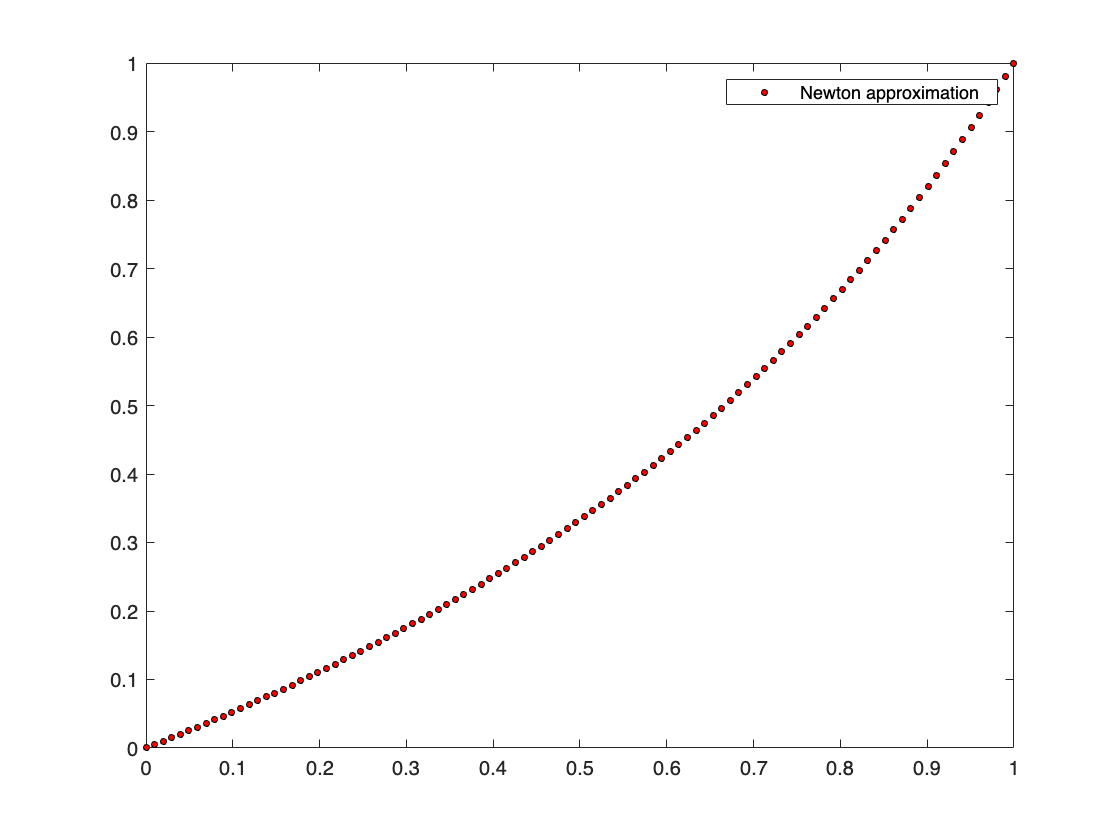

x=linspace(a,b,n+2)';

plot(x, u, 'ok', 'markerfacecolor', 'r', 'markersize', 3);
legend("Newton approximation")

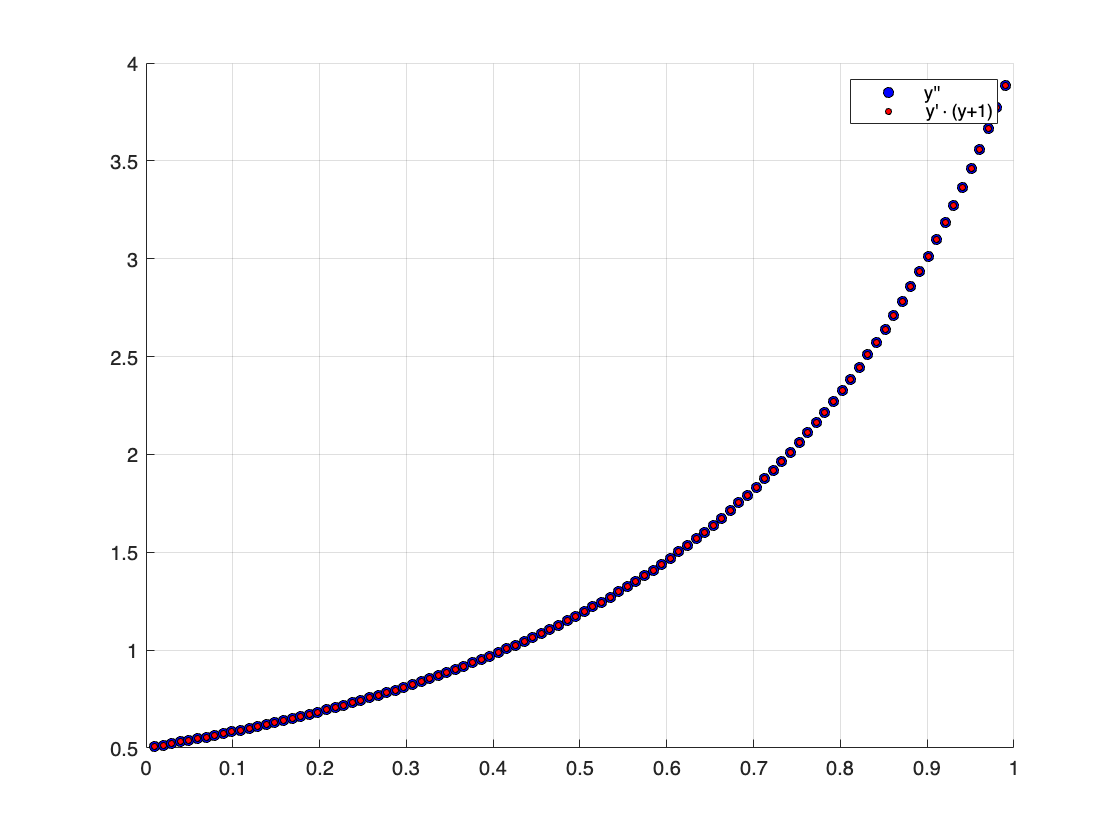

clf; hold on; grid on;
h=(b-a)/(n+1);
x=x(2:end-1);
y=u(2:end-1);
dy=(u(3:end)-u(1:end-2))/(2*h);
ddy=((u(3:end) - 2*u(2:end-1) + u(1:end-2)))/h^2;
plot(x, ddy, 'ok', 'markerfacecolor', 'b', 'markersize', 5)
plot(x, dy.*(1+y), 'ok', 'markerfacecolor', 'r', 'markersize', 3)
legend("y''", "y'\cdot(y+1)")